%"Dispatcher" by Kambadur Ananthamurthy
% This code uses actual dfbf curves from my data and analyses it for time
% cells using multiple methods
% Currently this is being tested for single session data. I will test with a
% batch, soon.

tic
clf
clear
close all


## Addpaths


addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions')) % my custom functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis')) % Additional functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth'))
addpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth/localCopies')


## Dataset


make_db
ops0.fig                       = 1;
ops0.saveData                  = 0;
ops0.onlyProbeTrials           = 0;
ops0.loadSyntheticData         = 1;
ops0.doSigOnly                 = 0;

if ops0.loadSyntheticData
    setupSyntheticDataParameters
end


## Figure details


if ops0.fig
    figureDetails = compileFigureDetails(20, 2, 10, 0.5, 'jet'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
end


## Main script

fprintf('Analyzing %s_%i_%i - Date: %s\n', db.mouseName, ...
    db.sessionType, ...
    db.session, ...
    db.date)

Analyzing M26_5_4 - Date: 20180514


saveDirec = '/Users/ananth/Desktop/Work/Analysis/Imaging/';
saveFolder = [saveDirec db.mouseName '/' db.date '/'];

%for i = 1:length(sdcp)
%i = 1;
i = length(sdcp);
if ops0.loadSyntheticData
    load([saveFolder ...
        'synthDATA' ...
        '-' num2str(i) ...
        '_tCP' num2str(sdcp(i).timeCellPercent) ...
        '_cO' lower(sdcp(i).cellOrder) ...
        '_mHTP' num2str(sdcp(i).maxHitTrialPercent) ...
        '_hTPA' lower(sdcp(i).hitTrialPercentAssignment) ...
        '_tO' lower(sdcp(i).trialOrder) ...
        '_eW' num2str(sdcp(i).eventWidth{1}) ...
        '_eAF' sdcp(i).eventAmplificationFactor ...
        '_eT' lower(sdcp(i).eventTiming) ...
        '_sF' num2str(sdcp(i).startFrame) ...
        '_eF' num2str(sdcp(i).endFrame) ...
        '_iFWHM' num2str(sdcp(i).imprecisionFWHM) ...
        '_iT' lower(sdcp(i).imprecisionType) ...
        '_n' lower(sdcp(i).noise) ...
        '_np' num2str(sdcp(i).noisePercent) ...
        '.mat']);
    myData.dfbf = sdo.syntheticDATA;
    myData.dfbf_2D = sdo.syntheticDATA_2D;
    myData.baselines = zeros(size(sdo.syntheticDATA)); %initialization
else
    %Load processed data (processed dfbf for dataset/session)
    myData = load([saveFolder db.mouseName '_' db.date '.mat']);
end
trialDetails = getTrialDetails(db);

Getting trial details ...
... done!



%Significant-Only Traces
if ops0.doSigOnly
    if ops0.onlyProbeTrials
        disp('Only analysing Probe Trials ...')
        dfbf_sigOnly = findSigOnly(myData.dfbf(:, iProbeTrials, :));
    else
        dfbf_sigOnly = findSigOnly(myData.dfbf);
    end
    DATA = dfbf_sigOnly;
else
    DATA = myData.dfbf;
end


## Analysis Pipeline: Method A - Mehrab's Reliability Analysis (Bhalla Lab)

mAInput.cellList = 1:1:size(DATA,1); %using all cells
mAInput.onFrame = sdcp.startFrame;
mAInput.offFrame = sdcp.endFrame;
mAInput.ridgeHalfWidth = 100; %in ms
mAInput.nIterations = 5000; %number of iterations of randomisation used to find averaged r-shifted rb ratio - might have to go as high as 3000.
mAInput.selectNonOverlappingTrials = 1; %1 - non-overlapping trial sets used for kernel estimation and rb ratio calculation, 0 - all trials used for both
mAInput.earlyOnly = 0; %0 - uses all trials; 1 - uses only the first 5 trials of the session
mAInput.startTrial = 1; %the analysis begins with this trial number (e.g. - 1: analysis on all trials)

[mAOutput] = runMehrabR2BAnalysis(DATA, mAInput, trialDetails);

Now calculating Ridge to Background Ratios ...
... 10 cells examined ...
... 20 cells examined ...
... 30 cells examined ...
... 40 cells examined ...
... 50 cells examined ...
... 60 cells examined ...
... 70 cells examined ...
... 80 cells examined ...
... 90 cells examined ...
... 100 cells examined ...
... 110 cells examined ...
... 120 cells examined ...
... 130 cells examined ...


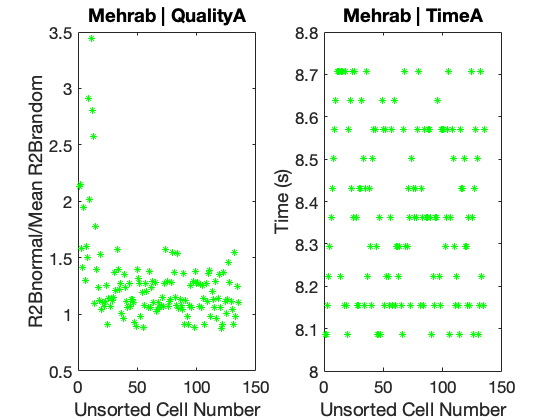


save([saveFolder db.mouseName '_' db.date '_methodA.mat' ], 'mAInput', 'mAOutput')

figure(1)
clf
subplot(1, 2, 1)
plot(mAOutput.Q, 'g*')
title('Mehrab | QualityA', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
%set(gca,'YTick',[10, 20, 30, 40, 50, 60])
%set(gca,'YTickLabel',({10; 20; 30; 40; 50; 60}))
ylabel('R2Bnormal/Mean R2Brandom', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 2, 2)
plot(mAOutput.T/db.samplingRate, 'g*')
title('Mehrab | TimeA', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
%set(gca,'YTick',[10, 20, 30, 40, 50, 60])
%set(gca,'YTickLabel',({10; 20; 30; 40; 50; 60}))
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)


if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodA_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodA_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

Undefined function or variable 'iexp'.

## Analysis Pipeline: Method B - William Mau's Temporal Information (Eichenbaum Lab)

mBInput = [];
[mBOutput] = runWilliamTIAnalysis(DATA);

save([saveFolder db.mouseName '_' db.date '_methodB.mat' ], 'mBInput', 'mBOutput')

figure(2)
clf
subplot(1, 2, 1)
plot(mBOutput.Q, 'b*')
title('William | QualityB' , ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
%set(gca,'YTick',[10, 20, 30, 40, 50, 60])
%set(gca,'YTickLabel',({10; 20; 30; 40; 50; 60}))
ylabel('Temporal Information (bits/spike)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

mbOutput.T = mCOutput.T; %!!
subplot(1, 2, 2)
plot((mBOutput.T * mCInput.delta)/db.samplingRate, 'g*')
title('William | TimeB', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
%set(gca,'YTick',[10, 20, 30, 40, 50, 60])
%set(gca,'YTickLabel',({10; 20; 30; 40; 50; 60}))
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodB_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodB_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

## Analysis Pipeline: Method C - Simple Analysis

mCInput.delta = 3;
mCInput.skipFrames = [];
mCInput.trialThreshold = 25; % in %

[mCOutput] = runSimpleTCAnalysis(DATA, mCInput);

save([saveFolder db.mouseName '_' db.date '_methodC.mat' ], 'mCInput', 'mCOutput')

figure(3)
clf
subplot(1, 2, 1)
plot(mCOutput.Q1, 'b*')
title('Simple | QualityC1' , ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
%set(gca,'YTick',[10, 20, 30, 40, 50, 60])
%set(gca,'YTickLabel',({10; 20; 30; 40; 50; 60}))
ylabel('Hit Trial Ratio * Kurtosis', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 2, 2)
plot((mCOutput.T * mCInput.delta)/db.samplingRate, 'g*')
title('Simple | TimeC', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
%set(gca,'YTick',[10, 20, 30, 40, 50, 60])
%set(gca,'YTickLabel',({10; 20; 30; 40; 50; 60}))
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC1_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC1_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

figure(4)
clf
subplot(1, 2, 1)
plot(mCOutput.Q2, 'b*')
%ylim([0 10])
title('Simple | QualityC2' , ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Cells', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
%set(gca,'YTick',[10, 20, 30, 40, 50, 60])
%set(gca,'YTickLabel',({10; 20; 30; 40; 50; 60}))
ylabel('Mean Timed Peak/Std Timed Peak', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 2, 2)
plot((mCOutput.T * mCInput.delta)/db.samplingRate, 'g*')
title('Simple | TimeC', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Cells', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
%set(gca,'YTick',[10, 20, 30, 40, 50, 60])
%set(gca,'YTickLabel',({10; 20; 30; 40; 50; 60}))
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC2_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC2_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

## Second Order Stats to compare the outputs

%Normalize the "reliability" vectors ignoring "Inf"
sdo.Q_norm = (sdo.Q) ./max(sdo.Q);
mAOutput.Q_norm = (mAOutput.Q) ./max(mAOutput.Q(~isinf(mAOutput.Q)));
mBOutput.Q_norm = (mBOutput.Q) ./max(mBOutput.Q);
mCOutput.Q1_norm = (mCOutput.Q1) ./max(mCOutput.Q1);
mCOutput.Q2_norm = (mCOutput.Q2) ./max(mCOutput.Q2);

fig5 = figure(5);
set(fig5,'Position',[300,300,1000,500])
clf
subplot(1, 4, 1)
scatter(sdo.Q_norm, mAOutput.Q_norm);
%         title('QA vs Q', ...
%             'FontSize', figureDetails.fontSize, ...
%             'FontWeight', 'bold')
xlabel('Normalized Q', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Normalized Ratio of R2B Ratios', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 2)
scatter(sdo.Q_norm, mBOutput.Q_norm);
%         title('QB vs Q', ...
%             'FontSize', figureDetails.fontSize, ...
%             'FontWeight', 'bold')
xlabel('Normalized Q', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Normalized TI', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 3)
scatter(sdo.Q_norm, mCOutput.Q1_norm);
%         title('QC1 vs Q', ...
%             'FontSize', figureDetails.fontSize, ...
%             'FontWeight', 'bold')
xlabel('Normalized Q', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Normalized HT Ratio * Kurtosis', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 4)
scatter(sdo.Q_norm, mCOutput.Q2_norm);
%         title('QC2 vs Q, ...
%             'FontSize', figureDetails.fontSize, ...
%             'FontWeight', 'bold')
xlabel('Normalized Q', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Normalized Mean Timed Peak/Std Timed Peak', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_normQScatter_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_normQScatter_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

fig6 = figure(6);
set(fig6,'Position',[300,300,1000,500])
clf
subplot(1, 4, 1)
scatter(mean(sdo.frameIndex, 2)/db.samplingRate, mAOutput.T/db.samplingRate);
%         title('TimeA vs Target Time', ...
%             'FontSize', figureDetails.fontSize, ...
%             'FontWeight', 'bold')
xlabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('TimeA (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 2)
scatter(mean(sdo.frameIndex, 2)/db.samplingRate, (mBOutput.T * mCInput.delta)/db.samplingRate);
%         title('TimeB vs Target Time', ...
%             'FontSize', figureDetails.fontSize, ...
%             'FontWeight', 'bold')
xlabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('TimeB (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 3)
scatter(mean(sdo.frameIndex, 2)/db.samplingRate, (mCOutput.T * mCInput.delta)/db.samplingRate);
%         title('TimeC1 vs Target Time', ...
%             'FontSize', figureDetails.fontSize, ...
%             'FontWeight', 'bold')
xlabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('TimeC (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 4)
scatter(mean(sdo.frameIndex, 2)/db.samplingRate, (sdo.T * mCInput.delta)/db.samplingRate);
%         title('Actual Time vs Target Time', ...
%             'FontSize', figureDetails.fontSize, ...
%             'FontWeight', 'bold')
xlabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Actual Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_TScatter_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_TScatter_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end
toc
disp('All done!')